# Resultados NR simultaneo vs solución analítica

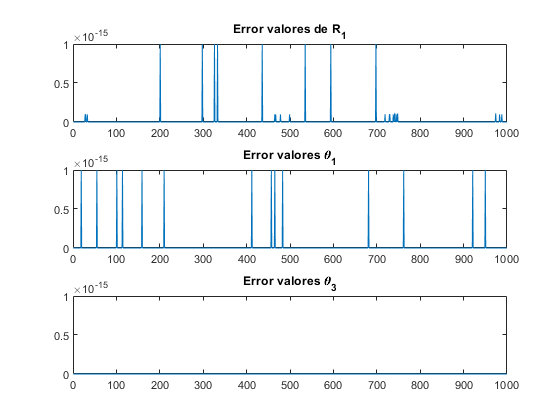

clear 
clc

Resultados_Analiticos=readtable("ResultadosAnaliticos.txt","Delimiter",' ');
Resultados_NR=readtable("Resultados.txt","Delimiter",' ');

ErrorR1=abs(Resultados_Analiticos.R_1-Resultados_NR.R_1);
ErrorTheta1=abs(Resultados_Analiticos.theta_1-Resultados_NR.theta_1);
ErrorTheta3=abs(Resultados_Analiticos.theta_3-Resultados_NR.theta_3);
ErrorV1=abs(Resultados_Analiticos.V_1-Resultados_NR.V_1);
ErrorW1=abs(Resultados_Analiticos.omega_1-Resultados_NR.omega_1);
ErrorW3=abs(Resultados_Analiticos.omega_3-Resultados_NR.omega_3);
ErrorA1=abs(Resultados_Analiticos.a_1-Resultados_NR.a_1);
ErrorAlpha1=abs(Resultados_Analiticos.alpha_1-Resultados_NR.alpha_1);
ErrorAlpha3=abs(Resultados_Analiticos.alpha_3-Resultados_NR.alpha_3);

figure()
subplot(3,1,1)
plot(ErrorR1)
title("Error valores de R_1")
ylim([0 10^-15])

subplot(3,1,2)
plot(ErrorTheta1)
title("Error valores \theta_1")
ylim([0 10^-15])

subplot(3,1,3)
plot(ErrorTheta3)
title("Error valores \theta_3")
ylim([0 10^-15])

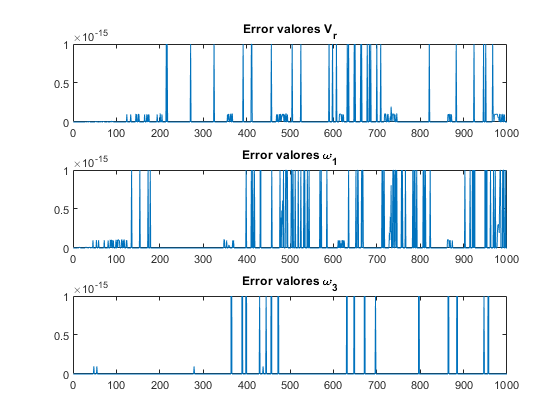


figure()
subplot(3,1,1)
plot(ErrorV1)
title("Error valores V_r")
ylim([0 10^-15])

subplot(3,1,2)
plot(ErrorW1)
title("Error valores \omega_1")
ylim([0 10^-15])

subplot(3,1,3)
plot(ErrorW3)
title("Error valores \omega_3")
ylim([0 10^-15])

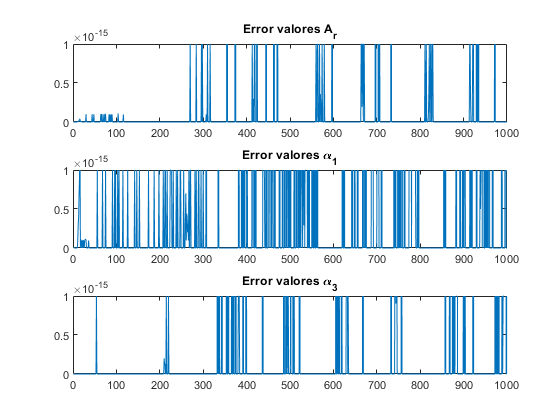


figure()
subplot(3,1,1)
plot(ErrorA1)
title("Error valores A_r")
ylim([0 10^-15])

subplot(3,1,2)
plot(ErrorAlpha1)
ylim([0 10^-15])
title("Error valores \alpha_1")

subplot(3,1,3)
plot(ErrorAlpha3)
title("Error valores \alpha_3")
ylim([0 10^-15])